# Sequence Classification Using 1-D Convolutions

This example shows how to classify sequence data using a 1-D convolutional neural network.

To train a deep neural network to classify sequence data, you can use a 1-D convolutional neural network. A 1-D convolutional layer learns features by applying sliding convolutional filters to 1-D input. Using 1-D convolutional layers can be faster than using recurrent layers because convolutional layers can process the input with a single operation. By contrast, recurrent layers must iterate over the time steps of the input. However, depending on the network architecture and filter sizes, 1-D convolutional layers might not perform as well as recurrent layers, which can learn long-term dependencies between time steps.

This example uses the Japanese Vowels data set described in [1] and [2]. This example trains a 1-D convolutional neural network to recognize the speaker given time series data representing two Japanese vowels spoken in succession. The training data contains time series data for nine speakers. Each sequence has 12 features and varies in length. The data set contains 270 training observations and 370 test observations.

## Load Sequence Data

Load the Japanese Vowels training data. The predictor data is a cell array containing sequences of varying length with 12 features. The target data is a categorical vector of labels "1","2",...,"9", which correspond to the nine speakers. The predictor sequences are matrices with 12 rows (one row for each feature) and a varying number of columns (one column for each time step).

load data.mat
load('matlab1DCNN.mat')
[ind.train,~,ind.test]=dividerand(378, 0.8, 0, 0.2);
ind_train=rawspeIR3_feacell(ind.train);
ind_test=rawspeIR3_feacell(ind.test);
Tind_train=CrawspeIR3_label(ind.train);
Tind_test=CrawspeIR3_label(ind.test);

## Define 1-D Convolutional Network Architecture

Define the 1-D convolutional neural network architecture. 

- Specify the input size as the number of features of the input data. 

- Specify two blocks of 1-D convolution, ReLU, and layer normalization layers, where the convolutional layer has a filter size of 3. Specify 32 and 64 filters for the first and second convolutional layers, respectively. For both convolutional layers, left-pad the inputs such that the outputs have the same length (causal padding).

- To reduce the output of the convolutional layers to a single vector, use a 1-D global average pooling layer.

- To map the output to a vector of probabilities, specify a fully connected layer with an output size matching the number of classes, followed by a softmax layer and a classification layer.

% filterSize = 3;
% numFilters = 64;
% numFeatures=201;
% numClasses=2;
% 
% layers = [ ...
%     sequenceInputLayer(numFeatures)
%     convolution1dLayer(filterSize,numFilters,Padding="causal")
%     reluLayer
%     layerNormalizationLayer
%     convolution1dLayer(filterSize,2*numFilters,Padding="causal")
%     reluLayer
%     layerNormalizationLayer
%     convolution1dLayer(filterSize,2*numFilters,Padding="causal")
%     reluLayer
%     layerNormalizationLayer
%     globalAveragePooling1dLayer
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer];

## Specify Training Options

Specify the training options:

- Train using the Adam optimizer.

- Train with a mini-batch size of 27 for 15 epochs.

- Left-pad the sequences.

- Validate the network using the validation data.

- Monitor the training progress in a plot and suppress the verbose output.

miniBatchSize = 64;

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=1000, ...
    SequencePaddingDirection="left", ...
    ValidationData={ind_test,Tind_test}, ...
    OutputNetwork="best-validation-loss",...
    Plots="training-progress", ...
    Verbose=1);

## Train Network

Train the network with the specified training options using the `trainNetwork` function.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       35.94% |       48.68% |       4.4295 |       2.6696 |          0.0010 |
|      13 |          50 |       00:00:05 |       62.50% |       73.68% |       1.3023 |       0.7785 |          0.0010 |
|      25 |         100 |       00:00:08 |       75.00% |       72.37% |       0.5599 |       0.5658 |          0.0010 |
|      38 |         150 |       00:00:11 |       84.38% |       89.47% |       0.3336 |       0.2459 |          0.0010 |
|      5

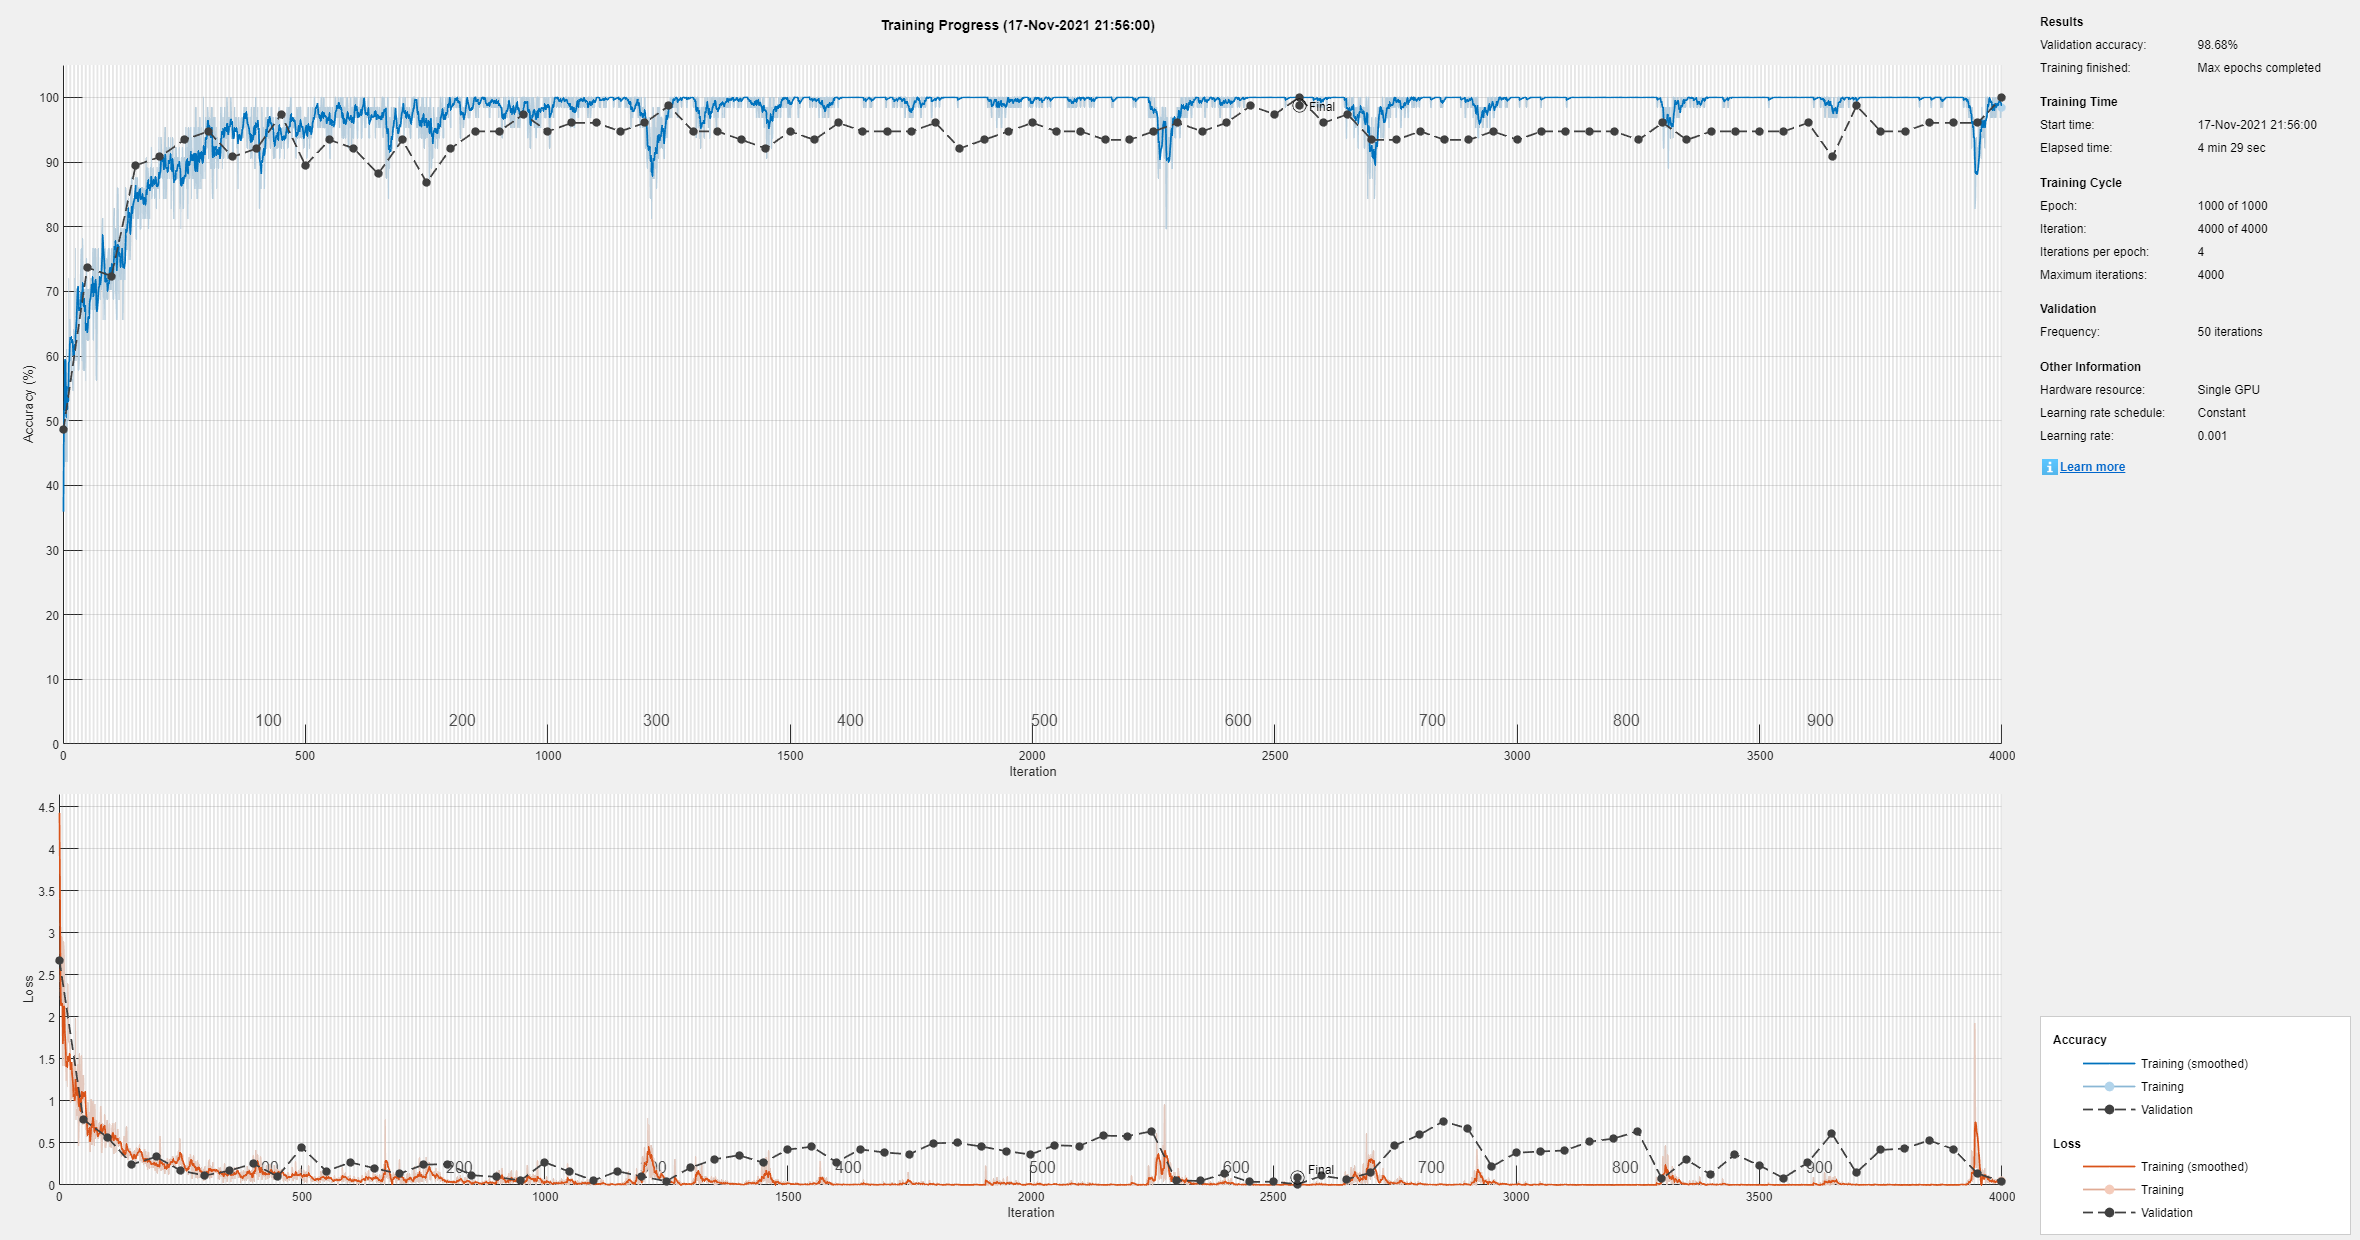

net = trainNetwork(ind_train,Tind_train,net,options);

## Test Network

Classify the validation data using the same mini-batch size and sequence padding options used for training.

YPred = classify(net,ind_test, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");

Calculate the classification accuracy of the predictions.

acc = mean(YPred == Tind_test)

acc = 0.9868

[c_matrix, order]=confusionmat(Tind_test,YPred);
    [R,R_Result]= Confusion.getValues(c_matrix)    %計算指標；各stage指標的順序與order相同

R = struct with fields:
                          Accuracy: 0.9868
                             Error: 0.0132
                       Sensitivity: 96.9697
                       Specificity: 100
                         Precision: 100
                 FalsePositiveRate: 0
                          F1_score: 98.4615
    MatthewsCorrelationCoefficient: 97.3477
                             Kappa: 97.3126


R_Result = struct with fields:
                  AccuracyOfSingle: 0.9697
                     ErrorOfSingle: 0.0303
                   AccuracyInTotal: 98.6842
                      ErrorInTotal: 1.3158
                       Sensitivity: 96.9697
                       Specificity: 100
                         Precision: 100
                 FalsePositiveRate: 0
                          F1_score: 98.4615
    MatthewsCorrelationCoefficient: 97.3477
                             Kappa: 97.3126
                      TruePositive: 32
                     FalsePositive: 0
                     FalseNegative: 1
                      TrueNegative: 43


Visualize the predictions in a confusion matrix.

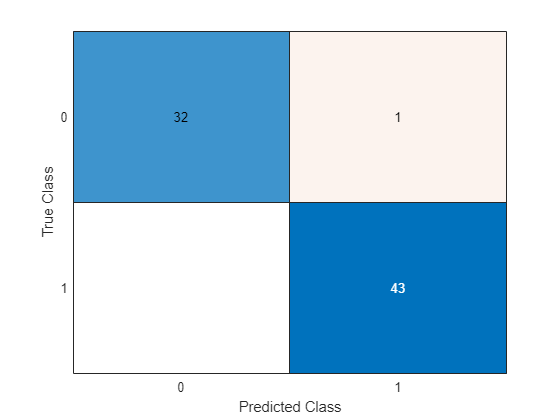

confusionchart(Tind_test,YPred)

## References

[1] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. “Multidimensional Curve Classification Using Passing-through Regions.” Pattern Recognition Letters 20, no. 11–13 (November 1999): 1103–11. [https://doi.org/10.1016/S0167-8655(99)00077-X](https://doi.org/10.1016/S0167-8655(99)00077-X) 

[2] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. "Japanese Vowels Data Set." Distributed by UCI Machine Learning Repository. [https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels](https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels) 

*Copyright 2021 The MathWorks, Inc.*